# Figure 9

## load data

whichData    = 'fmri1'; 
dataLoc      = fullfile(fileparts(temporalfMRIRootPath), 'files');

[a, b]       = loadfiles(dataLoc, whichData);
data_origDim = a.(whichData).data; % dimensions: 4 subjects x 9 rois x 100 bootstraps x 13 temporal conditions
roiNms       = a.(whichData).nm;
nRois        = length(roiNms);

smetrics{1} = b.fmri1.stn.derivedParam;
smetrics{2} = b.fmri1.stn_hrfFix.derivedParam;

hrf         = b.fmri1.hrf;

## average summary metrics

m_smetrics = {};
s_smetrics = {};

for iroi = 1 : nRois
    idx = (iroi - 1) *100 + 1 : iroi * 100;
    for k = 1 : 2
        m_smetrics{k}(iroi, 1) = median(smetrics{k}.r_double(idx));
        m_smetrics{k}(iroi, 2) = median(smetrics{k}.t_isi(idx));
        
        s_smetrics{k}(iroi, 1, :) = prctile(smetrics{k}.r_double(idx), [25, 75]);
        s_smetrics{k}(iroi, 2, :) = prctile(smetrics{k}.t_isi(idx), [25, 75]);
    end
end

## plot figure 9

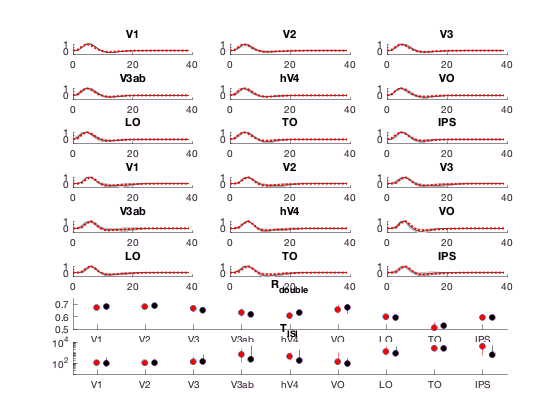

figure (9), clf
% plot hrf estimated from retinotopy data
for iroi = 1 : nRois
    subplot(8, 3, iroi)
    shadedErrorBar(hrf.ret_t, hrf.ret_mHrf(iroi, :), hrf.ret_sHrf(iroi, :), 'k'), hold on
    plot(hrf.ret_t, hrf.ret_mHrf(5, :), 'r:', 'linewidth', 2)
    ylim([-0.5, 1]), box off, title(roiNms(iroi))
end
% plot hrf estimated from the experiment
for iroi = 1 : nRois
    subplot(8, 3, 9 + iroi)
    shadedErrorBar(hrf.ret_t, hrf.exp_mHrf(iroi, :), hrf.exp_sHrf(iroi, :), 'k'), hold on
    plot(hrf.exp_t, hrf.exp_mHrf(5, :), 'r:', 'linewidth', 2)
    ylim([-0.5, 1]), box off, title(roiNms(iroi))
end
% compare summary metrics
markerColor = {'r', 'k'}; shift = [0, 0.2]; 
subplot(8, 3, 19 : 21)
for k1 = 1 : 2
    plot([1 : nRois]+shift(k1), m_smetrics{k1}(:, 1), 'o', 'markerfacecolor', markerColor{k1}), hold on
    for iroi = 1 : nRois
       plot([iroi, iroi] + shift(k1), squeeze(s_smetrics{k1}(iroi, 1, :)), '-', 'color', markerColor{k1}) 
    end
end
ylim([0.5, 0.75]), set(gca, 'xtick', 1 : nRois, 'xticklabel', roiNms), xlim([0.5, nRois + 0.5]), title('R_{double}'), box off

subplot(8, 3, 22 : 24)
for k1 = 1 : 2
    semilogy([1 : nRois]+shift(k1), m_smetrics{k1}(:, 2), 'o', 'markerfacecolor', markerColor{k1}), hold on
    for iroi = 1 : nRois
       semilogy([iroi, iroi] + shift(k1), squeeze(s_smetrics{k1}(iroi, 2, :)), '-', 'color', markerColor{k1}) 
    end
end
ylim([10, 10^4]), set(gca, 'xtick', 1 : nRois, 'xticklabel', roiNms), xlim([0.5, nRois + 0.5]), title('T_{ISI}'), box off